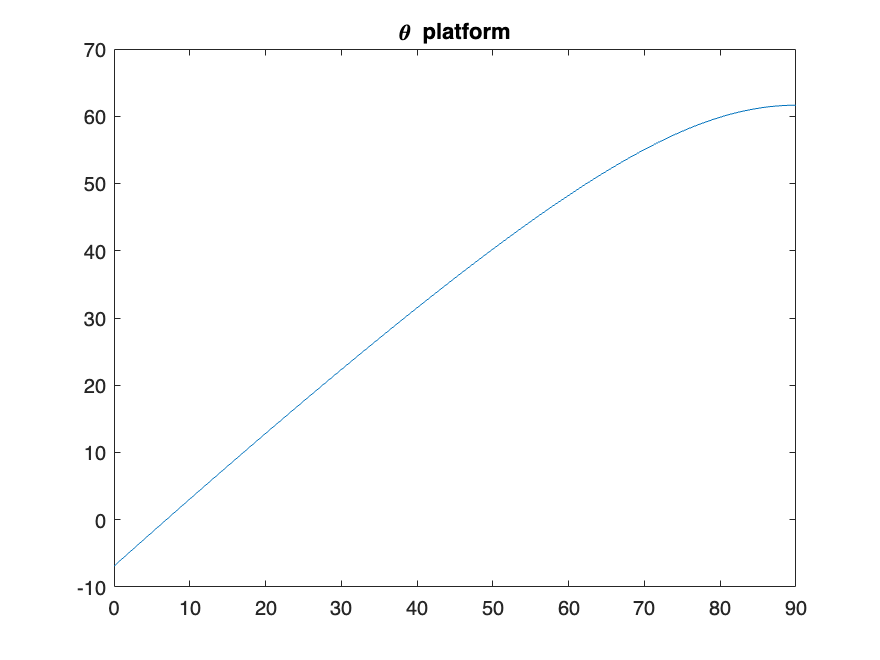

theta_max = [linspace(0,90,1000)]*pi/180;

cl = 2;
h_bak = 0.24;
theta_platform = asin((cl*sin(theta_max)-h_bak)/cl);
plot(theta_max*180/pi,theta_platform*180/pi)
title('\theta platform')

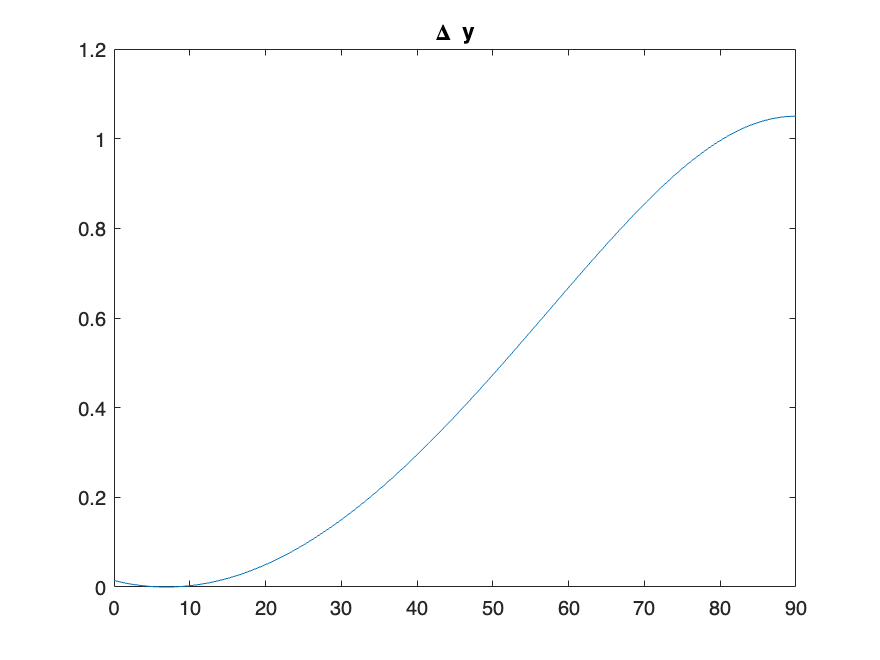

dy = cl -cl*cos(theta_platform);
plot(theta_max*180/pi,dy)
title('\Delta y')

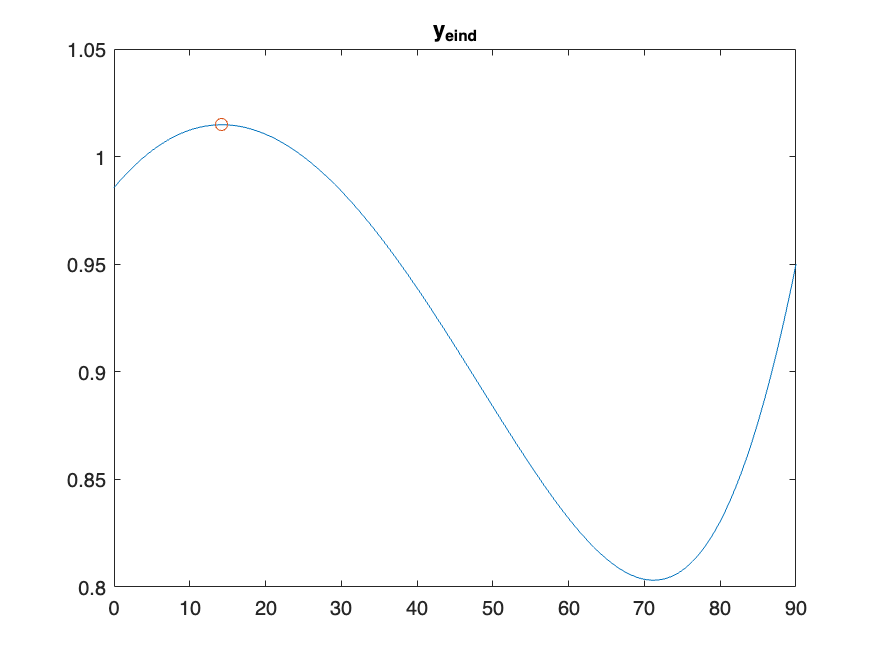

y_eind = cl - cos(theta_max) -dy;
[M,I]= max(y_eind);
plot(theta_max*180/pi,y_eind)
hold on
scatter(theta_max(I)*180/pi , y_eind(I))
hold off
title('y_{eind}')

theta_max(I)*180/pi

ans = 14.2342